syms Y
syms x(t) z(t)
y = 0.46

y =    0.460000000000000


yaw = 0*pi/180;
pitch = 0;

delta=10*pi/180

delta =    0.174532925199433


roll=-10*pi/180

roll =   -0.174532925199433


thrust = 0

thrust =      0



sideslipangf=0*pi/180;
sideslipangr=0*pi/180;
swingarmang = 30*pi/180;


epsilon=0.43; %steering head angle 
daero=0.28; %aero damping coeff
ksr=92000;ksf=84400; % lateral stiffnesses of tires
lr=0.3;lf=0.18; % rest length of rear and front suspension
l1=0.25;l2=0.5; % length from rear frame CoM to swingarm joint and steering column joint respectively
l3=0.265;l4=0.265; % length from swingarm joint to swingarm CoM and length from CoM to rear wheel respectively
l5=0.098;l6=0.268; % length from steering joint to steering CoM and length from CoM to where suspension begins respectively
l7=0.122; % length from where suspension begins to CoM of iverted fork
l8=0.1; % length from swingarm joint to where rear suspension meets rear frame
Rr=0.317;Rf=0.292; % rolling radius rear and front
tr=0.097;tf=0.062; % radius of cross section rear and front
Ir=0.66;If=0.47; % Moment of inertia tires
g=9.8;
Ma=223; % rear frame mass including rider
Mb=10.0; % swingarm mass 
Mc=7.0; % front unsprung mass
Md=16.2; % rear wheel mass
Mg=12.0; % front wheel mass
Mf=8.75; % steering column mass
M = Ma+Mb+Mc+Md+Mf+Mg;

xi = epsilon;
frontWcamber = asin(cos(delta)*sin(roll) - cos(roll)*sin(delta)*sin(xi))

frontWcamber =   -0.244734945966582


kinsteeringang = atan((sin(delta)*cos(xi))/(cos(roll)*cos(delta) + sin(delta)*sin(roll)*sin(xi)))

kinsteeringang =    0.163414434140871




%transformation matrices
syms un mn dm ad ba ea fe gf hg mh [3 3]

un(1,1)=sin(atan(diff(z,t)/diff(x,t)));un(1,2)=0;un(1,3)=cos(atan(diff(z,t)/diff(x,t)));
un(2,1)=0;un(2,2)=1;un(2,3)=0;
un(3,1)=-cos(atan(diff(z,t)/diff(x,t)));un(3,2)=0;un(3,3)=sin(atan(diff(z,t)/diff(x,t)));

mn(1,1)=cos(yaw);mn(1,2)=0;mn(1,3)=-sin(yaw);
mn(2,1)=0;mn(2,2)=1;mn(2,3)=0;
mn(3,1)=sin(yaw);mn(3,2)=0;mn(3,3)=cos(yaw);

dm(1,1)=1;dm(1,2)=0;dm(1,3)=0;
dm(2,1)=0;dm(2,2)=cos(roll);dm(2,3)=sin(roll);
dm(3,1)=0;dm(3,2)=-sin(roll);dm(3,3)=cos(roll);

ad(1,1)=cos(pitch);ad(1,2)=sin(pitch);ad(1,3)=0;
ad(2,1)=-sin(pitch);ad(2,2)=cos(pitch);ad(2,3)=0;
ad(3,1)=0;ad(3,2)=0;ad(3,3)=1;

ba(1,1)=cos(swingarmang);ba(1,2)=sin(swingarmang);ba(1,3)=0;
ba(2,1)=-sin(swingarmang);ba(2,2)=cos(swingarmang);ba(2,3)=0;
ba(3,1)=0;ba(3,2)=0;ba(3,3)=1;

ea(1,1)=cos(epsilon);ea(1,2)=sin(epsilon);ea(1,3)=0;
ea(2,1)=-sin(epsilon);ea(2,2)=cos(epsilon);ea(2,3)=0;
ea(3,1)=0;ea(3,2)=0;ea(3,3)=1;

fe(1,1)=cos(delta);fe(1,2)=0;fe(1,3)=-sin(delta);
fe(2,1)=0;fe(2,2)=1;fe(2,3)=0;
fe(3,1)=sin(delta);fe(3,2)=0;fe(3,3)=cos(delta);

gf(1,1)=cos(xi);gf(1,2)=-sin(xi);gf(1,3)=0;
gf(2,1)=sin(xi);gf(2,2)=cos(xi);gf(2,3)=0;
gf(3,1)=0;gf(3,2)=0;gf(3,3)=1;

hg(1,1)=1;hg(1,2)=0;hg(1,3)=0;
hg(2,1)=0;hg(2,2)=cos(frontWcamber);hg(2,3)=-sin(frontWcamber);
hg(3,1)=0;hg(3,2)=sin(frontWcamber);hg(3,3)=cos(frontWcamber);

mh(1,1)=cos(kinsteeringang);mh(1,2)=0;mh(1,3)=sin(kinsteeringang);
mh(2,1)=0;mh(2,2)=1;mh(2,3)=0;
mh(3,1)=-sin(kinsteeringang);mh(3,2)=0;mh(3,3)=cos(kinsteeringang);

nm=inv(mn);md=inv(dm);da=inv(ad);ab=inv(ba);ae=inv(ea);ef=inv(fe);fg=inv(gf);gh=inv(hg);hm=inv(mh);

% coords of 6 bodies CoM in U (universal) frame
% A - rear frame
% B - swimngarm
% C - front unsprung mass
% D - rear wheel
% G - front wheel
% F - steering column
% N - ground
syms A B D F C G [1 3] %#ok<*NASGU>

A(1)=x;A(2)=y;A(3)=z;
B = A - [l1 0 0]*nm*md*da - [l3 0 0]*nm*md*da*ab; %#ok<*MINV> 
D = B - [l4 0 0]*nm*md*da*ab;
F = A + [l2 0 0]*nm*md*da - [0 l5 0]*nm*md*da*ae*ef;
C = F - [0 l6+l7 0]*nm*md*da*ae*ef;
G = F - [0 l6+0.18 0]*nm*md*da*ae*ef;

Ax=A(1);Ay=A(2);Az=A(3);
Bx=B(1);By=B(2);Bz=B(3);
Dx=D(1);Dy=D(2);Dz=D(3);
Fx=F(1);Fy=F(2);Fz=F(3);
Cx=C(1);Cy=C(2);Cz=C(3);
Gx=G(1);Gy=G(2);Gz=G(3);

% contact points rear and front
syms Cr Cf [1 3]

Cr = D + [0 -Rr*cos(roll) Rr*sin(roll)]*nm*md;
Cf = G + [0 -Rf*cos(frontWcamber) Rf*sin(frontWcamber)]*nm*md*da*ae*ef*fg;
Crx=Cr(1);Cry=Cr(2);Crz=Cr(3);
Cfx=Cf(1);Cfy=Cf(2);Cfz=Cf(3);

fw=0.02; %rolling resistance coeff
maxsideslipr=16*pi/180;maxsideslipf = 16*pi/180;
maxpneumatictrailf=0.03;maxpneumatictrailr=0.03;

% some more geometry parameters
b = Ax - Crx;
b = vpa(b)

$$b = 0.70899346400575248278477328049906$$

p = Cfx - Crx;
p = vpa(p)

$$p = 1.0250071998987381196013378552907$$

h = y;
dr = fw*Rr;
df = fw*Rf;
sr = tr*tan(roll);
sf = tf*tan(roll);

pneumatictrailr = maxpneumatictrailr*(1 - (sideslipangr/maxsideslipr));
pneumatictrailf = maxpneumatictrailf*(1 - (sideslipangf/maxsideslipf));

% FORCES & WORKFUNCTIONS %
% rear wheel
    % thrust acts in in +x dir in D frame
Wthrust = transpose(un*nm*md*[thrust;0;0])*[Crx;Cry;Crz]

$$Wthrust = 0$$

    % normal reactional force +y dir in N frame acts at dr preceding Cr
Nr = M*g*(p-b)/p  + thrust*h/p

$$Nr = 836.77074737547625647881817609906$$

%WNr = [0 Nr 0]*[Crx;Cry;Crz]
    % longitudinal slip calc
Bk=1.2889;
Ck=0.8480;
Dk=1.2;
Ek=-0.6361;
kk = Dk*Ck*Bk;
% longislip = thrust/(kk*Nr); % linear fit
longislip = erfinv(thrust/(Dk*Nr)); % rather insulting way to find inverse to pacejka's magic formula
    % Lateral force acts in +z dir in D frame
Ds=1.1;
Bl=7;
Cl=1.3;
El=-0.3;
kl = Ds*Cl*Bl;
Bp=0.714;
Cp=1.4;
Ep=-2;
kp = Ds*Cp*Bp;
latforcer = Ds*Nr*(sin(Cl*atan(Bl*sideslipangr - El*(Bl*sideslipangr-atan(Bl*sideslipangr)))) + sin(Cp*atan(Bp*roll - Ep*(Bp*roll-atan(Bp*roll)))))

$$latforcer = -160.5567752579896941693323251001$$

% latforcer = (kl*sideslipangr + kp*roll)*Nr;
spr = latforcer/ksr;
Wlatforcer = transpose(un*nm*md*[0;0;latforcer])*[Crx;Cry;Crz]

$$Wlatforcer = \begin{array}{l} \frac{158.11755707270691951798851809269\,\left(\frac{53\,\sqrt{3}}{200}-x\left(t\right)+\frac{1}{4}\right)}{\sigma_{1}}-\frac{158.11755707270691951798851809269\,\left(z\left(t\right)-\frac{15637522963647884060132322356912}{144230468292634088814079842706329}\right)\,\frac{\partial }{\partial t}z\left(t\right)}{\sigma_{1}\,\frac{\partial }{\partial t}x\left(t\right)}-11.908201394182361972229752967626\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{{\left(\frac{\partial }{\partial t}z\left(t\right)\right)}^{2}}{{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}+1} \end{array}$$

%     % torque due to thrust/brake affects yaw
% Tthrustr = (sr+spr)*thrust;
% Mthrustr = Tthrustr*yaw;
%     % torque due to pneumatic trail affects yaw
% Ttrailr = pneumatictrailr*latforcer;
% Mtrailr = Ttrailr*yaw;
%     % torque due to rolling resistance affects swingarmangle
% Trollresr = dr*Nr;
% Mrollresr = Trollresr*swingarmang;
%     % torque due to overturning affects roll
% Toverturnr = -spr*Nr;
% Moverturnr = Toverturnr*roll;


% front wheel
    %normal reactional force +y dir in N frame acts at df preceding Cf
Nf = M*g*b/p  - thrust*h/p

$$Nf = 1877.3392526245238708504400721109$$

% WNf = [0 Nf 0]*[Cfx;Cfy;Cfz];
    % lateral force acts in +z dir in G frame
latforcef = Ds*Nf*(sin(Cl*atan(Bl*sideslipangf - El*(Bl*sideslipangf-atan(Bl*sideslipangf)))) + sin(Cp*atan(Bp*frontWcamber - Ep*(Bp*frontWcamber-atan(Bp*frontWcamber)))))

$$latforcef = -504.771438265232529013576730036$$

% latforcef = (kl*sideslipangr + kp*roll)*Nf;
spf = latforcef/ksf;
Wlatforcef = transpose(nm*md*da*ae*ef*fg*[0;0;latforcef])*[Cfx;Cfy;Cfz]

$$Wlatforcef = 139.64202407278268328806457830546-483.20564270309071560698730324287\,z\left(t\right)-79.673247985872774732435350339705\,x\left(t\right)$$

%     % torque due to pneumatic trail affects steeringangle 
% Ttrailf = pneumatictrailf*latforcef;
% Mtrailf = Ttrailf*delta;
%     % torque due to thrust/brake affects steeringangle
% Tthrustf = (sr+spr)*thrust;
% Mthrustf = Tthrustf*delta;
%     % torque due to rolling resistance affects pitch
% Trollresf = df*Nf;
% Mrollresf = Trollresf*pitch;
%     % torque due to overturning affects frontwheelcamber
% Toverturnf = -spf*Nf;
% Moverturnf = Toverturnf*frontWcamber;

Workfunc = Wthrust + Wlatforcer + Wlatforcef

$$Workfunc = \begin{array}{l} \frac{158.11755707270691951798851809269\,\left(\frac{53\,\sqrt{3}}{200}-x\left(t\right)+\frac{1}{4}\right)}{\sigma_{1}}-483.20564270309071560698730324287\,z\left(t\right)-79.673247985872774732435350339705\,x\left(t\right)-\frac{158.11755707270691951798851809269\,\left(z\left(t\right)-\frac{15637522963647884060132322356912}{144230468292634088814079842706329}\right)\,\frac{\partial }{\partial t}z\left(t\right)}{\sigma_{1}\,\frac{\partial }{\partial t}x\left(t\right)}+127.73382267860032131583482533784\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{{\left(\frac{\partial }{\partial t}z\left(t\right)\right)}^{2}}{{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}+1} \end{array}$$


% dissipative functions
    % aerodynamic drag
Daero = 0.5*daero*(((diff(x,t))^2 + (diff(y,t))^2 + (diff(z,t))^2));
Diss = Daero;

KE = 0.5*M*((diff(x,t))^2 + (diff(y,t))^2 + (diff(z,t))^2);
PE = M*g*y;
L = KE - PE;
eqn1 = diff(diff(L,diff(x,t)),t) - diff(L,x) + diff(Diss,diff(x,t)) == diff(Workfunc,x);
eqn2 = diff(diff(L,diff(z,t)),t) - diff(L,z) + diff(Diss,diff(z,t)) == diff(Workfunc,z);

eqns = [eqn1;eqn2]

$$eqns(t) = \begin{array}{l} \left(\begin{array}{c} \frac{5539\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{20}+\frac{7\,\frac{\partial }{\partial t}x\left(t\right)}{25}=-\frac{158.11755707270691951798851809269}{\sigma_{1}}-79.673247985872774732435350339705\\ \frac{5539\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)}{20}+\frac{7\,\frac{\partial }{\partial t}z\left(t\right)}{25}=-\frac{158.11755707270691951798851809269\,\frac{\partial }{\partial t}z\left(t\right)}{\sigma_{1}\,\frac{\partial }{\partial t}x\left(t\right)}-483.20564270309071560698730324287 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{{\left(\frac{\partial }{\partial t}z\left(t\right)\right)}^{2}}{{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}+1} \end{array}$$


[VF,Subs] = odeToVectorField(eqns)

$$VF = \left(\begin{array}{c} Y_{2}\\ -\frac{28\,Y_{2}}{27695}-\frac{0.5709245606524893284635801339328\,Y_{2}}{Y_{4}\,\sqrt{\frac{{Y_{2}}^{2}}{{Y_{4}}^{2}}+1}}-1.7447396378519253136197411202126\\ Y_{4}\\ -\frac{0.5709245606524893284635801339328}{\sqrt{\frac{{Y_{2}}^{2}}{{Y_{4}}^{2}}+1}}-\frac{28\,Y_{4}}{27695}-0.28768098207572765745598609980034 \end{array}\right)$$

$$Subs = \left(\begin{array}{c} z\\ \mathrm{Dz}\\ x\\ \mathrm{Dx} \end{array}\right)$$

odefcn = matlabFunction(VF, 'Vars',{t,Y});
[X,Y] = ode45(odefcn, [0 10], [0 0 0 5/3.6]);
Y

Y =                    0                   0                   0   1.388888888888889
  -0.000000000723265  -0.000050237430586   0.000039991067759   1.388864125919262
  -0.000000002893050  -0.000100474265074   0.000079981422498   1.388839362950377
  -0.000000006509337  -0.000150710503449   0.000119971064216   1.388814599982257
  -0.000000011572108  -0.000200946145699   0.000159959992914   1.388789837014921
  -0.000000058582638  -0.000452115414556   0.000359893941094   1.388666022190779
  -0.000000141752716  -0.000703269778137   0.000559810063764   1.388542207389499
  -0.000000261080195  -0.000954409234679   0.000759708360926   1.388418392613773
  -0.000000416562930  -0.001205533782418   0.000959588832586   1.388294577866291
  -0.000001736230294  -0.002460932827456   0.001958723808497   1.387675504646839


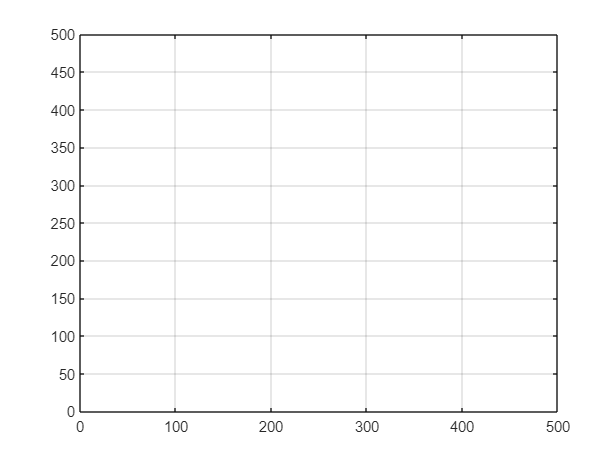

plot(Y(:,1),Y(:,3))
axis([0 500 0 500])
grid